#### Set project directory information

% Code to run on Mac platform
if isunix
    PRJ_DIR = "";
elseif ispc
    PRJ_DIR = "G:\HongLab @ Caltech Dropbox\Remy\mb_odor_rearing";
else
    disp('Platform not supported')
end

#### Set date, fly, movie name

- Set analysis directory ()

 
directories = uigetfile_n_dir(char(PRJ_DIR), 'Select folders for saving new CNMF options')';
directories = directories(isfolder(directories));
disp(directories)

    {'G:\HongLab @ Caltech Dropbox\Remy\mb_odor_rearing\processed_data\2021-03-23\1\movie\split stacks\stk_0001'}



% 
% date = "2021-03-23";
% fly_num = 1;
% nam = "movie";
% SAVE_DIR = fullfile(PRJ_DIR, "processed_data",date,num2str(fly_num),nam)
% SPLITSTACK_DIR = fullfile(SAVE_DIR, "split stacks");
% listing = subdir(SPLITSTACK_DIR);

 
d1 = 256

d1 = 256

d2 = 256

d2 = 256

fr = 4.5

fr = 4.5000


K = 400;            % # of expected components
tau = [3 3];        % expected size of components
p = 0;              % order of autoregressive system 
                   % (p = 0 no dynamics, p=1 just decay, p = 2, both rise and decay)
merge_thr = .85;      % merging threshold


options = CNMFSetParms(...   
    'd1',d1,'d2',d2,...                         % dimensions of datasets
    'fr', fr,...
    'p',p,...                                   % order of AR dynamics    
    'gSig',tau,...                                % half size of neuron
    'merge_thr',merge_thr,...                        % merging threshold  
    'nb', 2,...                                  % number of background components    
    'min_SNR',3,...                             % minimum SNR threshold
    'noise_norm', false,...
    'rem_prct', 0,...
    'bas_nonneg', false,...
    'space_thresh',0.4,...                      % space correlation threshold
    'time_thresh',0.4,...                      % space correlation threshold
    'cnn_thr',0.2,...                            % threshold for CNN classifier    
    'init_method', 'greedy',...
    'search_method', 'ellipse',...
    'dist', 2,...
    'max_size', 4,...
    'min_size', 3, ...
    'clos_op', strel('square',2),...
    'spatial_method', 'regularized',...
    'thr_method', 'nrg',...
    'nrgthr', .98,...
    'min_pixel', 10,...
    'cluster_pixels', true,...
    'extract_max', true,...
    'bd', 30, ...
    'fast_merge', true ...
    );

for i = 1:length(directories)
    cnmf_dir = fullfile(directories{i}, 'cnmf');
    if ~exist(cnmf_dir, 'dir')
        mkdir(cnmf_dir);
    end
    save(fullfile(cnmf_dir, 'cnmfoptions.mat'), 'options', 'K', 'tau', 'p');
end

 
fprintf('Running CNMF in folders:\n');

Running CNMF in folders:


----------------------------------------------------------

	G:\HongLab @ Caltech Dropbox\Remy\mb_odor_rearing\processed_data\2021-03-23\1\movie\split stacks\stk_0001...

The file was loaded successfully. Elapsed time : 0.736 s.
Estimating the noise power for each pixel from a simple PSD estimate...  done 
No spatial downsampling is performed. Consider spatial downsampling if the field of view is very large. 
No temporal downsampling is performed. Consider temporal downsampling if the recording is very long. 
starting resampling 
Initializing components with greedy method 
found 10 out of 400 neurons..
found 20 out of 400 neurons..
found 30 out of 400 neurons..
found 40 out of 400 neurons..
found 50 out of 400 neurons..
found 60 out of 400 neurons..
found 70 out of 400 neurons..
found 80 out of 400 neurons..
found 90 out of 400 neurons..
found 100 out of 400 neurons..
found 110 out of 400 neurons..
found 120 out of 400 neurons..
found 130 out of 400 neurons..
found 140 out of 400 neurons..
found 150 out of 400 neurons..
found 160 out of 400 neurons..
found 170 out of 400 neurons..
found 180 out of 400 neurons..
found 190 out of 400 neurons..
found 200 o

  done 
Updated spatial components 


10 out of total 400 temporal components updated 
20 out of total 400 temporal components updated 
30 out of total 400 temporal components updated 
40 out of total 400 temporal components updated 
50 out of total 400 temporal components updated 
60 out of total 400 temporal components updated 
70 out of total 400 temporal components updated 
80 out of total 400 temporal components updated 
90 out of total 400 temporal components updated 
100 out of total 400 temporal components updated 
110 out of total 400 temporal components updated 
120 out of total 400 temporal components updated 
130 out of total 400 temporal components updated 
140 out of total 400 temporal components updated 
150 out of total 400 temporal components updated 
160 out of total 400 temporal components updated 
170 out of total 400 temporal components updated 
180 out of total 400 temporal components updated 
190 out of total 400 temporal components updated 
200 out of total 400 temporal components updated 
210 out o

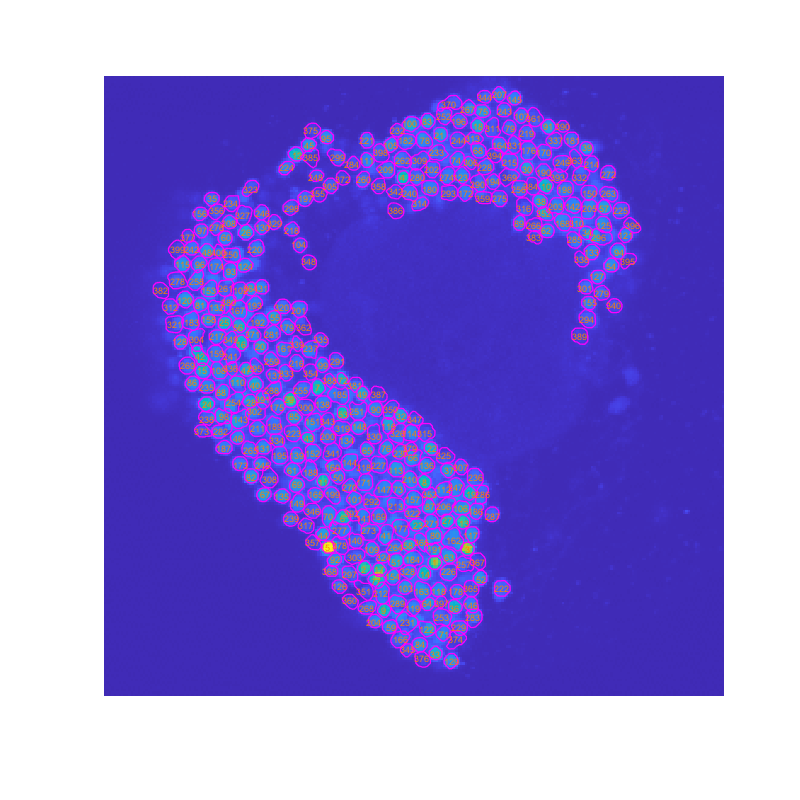

		done


for i = 1:length(directories)
    fprintf('----------------------------------------------------------')
    fprintf('\t%s...', directories{i});
    run_cnmf_in_folder(directories{i});
    fprintf('\t\tdone\n');
end